Datasets were downloaded from:

Environmental Data Initiative: 

- doi:10.6073/pasta/bce9fe91713f06d66aec66a161b41f5d

- doi:10.6073/pasta/7f8e5d24e9b27ae695295a8ddc0809d1

CCE LTER Datazoo:

    [https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/57](https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/57)

    [https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/194](https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/194)

    [https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/113](https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/113)

    [https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/153](https://oceaninformatics.ucsd.edu/datazoo/catalogs/ccelter/datasets/153)

Zooscan Database: [https://oceaninformatics.ucsd.edu/zooscandb/](https://oceaninformatics.ucsd.edu/zooscandb/)

Jacox Upwelling Indices Website: [https://mjacox.com/upwelling-indices/](https://mjacox.com/upwelling-indices/)

Datasets were then opened and basic processing was undertaken (Appending dates, latitudes, and longitudes where necessary).  The summary data is then saved as 'TimeSeries.mat' in the 'Processed Data' folder so that it can be used in future code.

OpenTimeSeries

Next some of the microbial datasets (epifluorescence microscopy, flow cytometry, and net primary productivity) were opened and the surface values and vertically integrated values were extracted.  This was done because it is unlikely that vertically resolved data would be used.

VerticallyIntegrate

We have three potential disturbance time-series.  Two of them (BEUTI and San Diego SLA) are time-series that apply to the entire region.  The third is water parcel age, which is spatially variable.  Water parcel ages (defined as time since the water parcel passed the 500 m isobath) was calculated based on a backward in time Lagrangian trajectory calculation forced with satellite-derived surface ocean currents (for additional details see: Chabert et al. 2021, JGR:O, doi: 10.1029/2020JC0166112 of 14).  This data is not (to my knowledge) publicly available, so I requested it from Pierre Chabert.  As it is not my data, I don't feel comfortable posting it.  Hence, the following lines won't actually run on the server.  However, the resultant files which include the matched water parcel age for each sampling station are hosted.

AppendWaterAge

Data is now saved in 'TimeSeries w waterparcel ages.mat'

Next, we focused on making a plot that relates primary producer and consumer biomass to water age as defined in Chabert et al. (2021, JGR:O).  We plotted phytoplankton biomass (which is summed epifluorescence microscopy biomass + Synechococcus + Prochlorococcus).  We plotted NPP (note that this is in the weird CalCOFI units which is mg C fixed per meter squared over a half photoperiod, i.e., from sunrise until noon).  We plotted heterotrophic protist biomass (all from epifluorescence microscopy, and hence prone to all the caveats with missing ciliates and difficulty accurately differentiating autotrophs from heterotrophs).  And we plotted herbivorous metazoan zooplankton, which here I have defined as the biomass of Calanoid copepods + Euphausiids + Pelagic Tunicates.  Only night-time net tows were used for metazoan zooplankton to avoid issues introduced by diel vertically migrating taxa. 

StandingStockvWaterAge

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 0

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

Next, I went ahead and made a time-series plot that shows long-term time-series of the same parameters.  Note that for this plot you can choose the station that you want to plot.  This plot uses the same definitions of organisms as the previous plot.  San Diego de-trended sealevel anomaly is added as an additional time series in each figure and is used as a proxy for the local ENSO index.  

station = [80,55];
StandardTimeseriesPlots(station)

ans = 0

We needed a static diagram that highlights changes mediated through the consumers.  An interesting example of this that occurs in CCE is a bloom of thaliaceans (salps, doliolids, and pyrosomes).  I did not have great data on hand for ecosystem changes in response to a thaliacean bloom in CCE (where I lack control data to use), but the SalpPOOP cruise off of New Zealand provided an excellent example.  This data comes mostly from Decima et al. (2023, Nat. Comm.) although some of it is from Stukel et al. (in prep.)

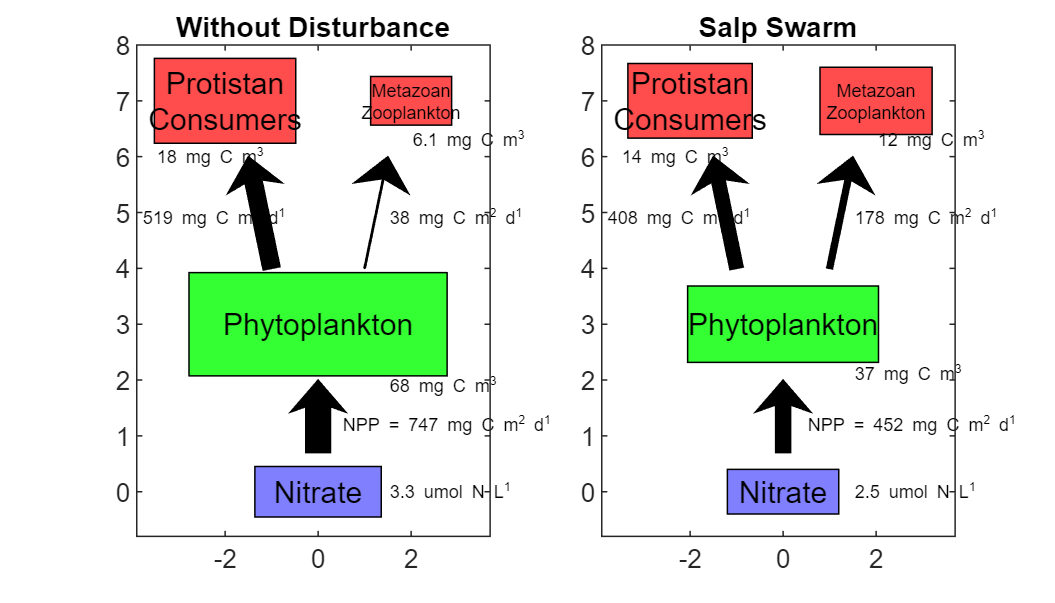

SalpStatic

I edited this figure in Photoshop to add images of the different organisms.